syms y(t)
eqn = diff(y, t) == -12 * y;
cond = y(0) == 1;
dsolve(eqn, cond);
exactSol = @(t)exp(-12 * t);

f = @(t, y) -12 * y;
a = 0;
b = 1;
alpha = 1;

N1 = 20;
N2 = 50;
N3 = 100;
N = [N1, N2, N3];

[y0,t0] = RK4(f, a, b, alpha, N1)

y0 =     1.0000
    0.5494
    0.3018
    0.1658
    0.0911
    0.0501
    0.0275
    0.0151
    0.0083
    0.0046


t0 =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


[y1,t1] = RK4(f, a, b, alpha, N2)

y1 =     1.0000
    0.7866
    0.6188
    0.4868
    0.3829
    0.3012
    0.2369
    0.1864
    0.1466
    0.1153


t1 =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


[y2,t2] = RK4(f, a, b, alpha, N3)

y2 =     1.0000
    0.8869
    0.7866
    0.6977
    0.6188
    0.5488
    0.4868
    0.4317
    0.3829
    0.3396


t2 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


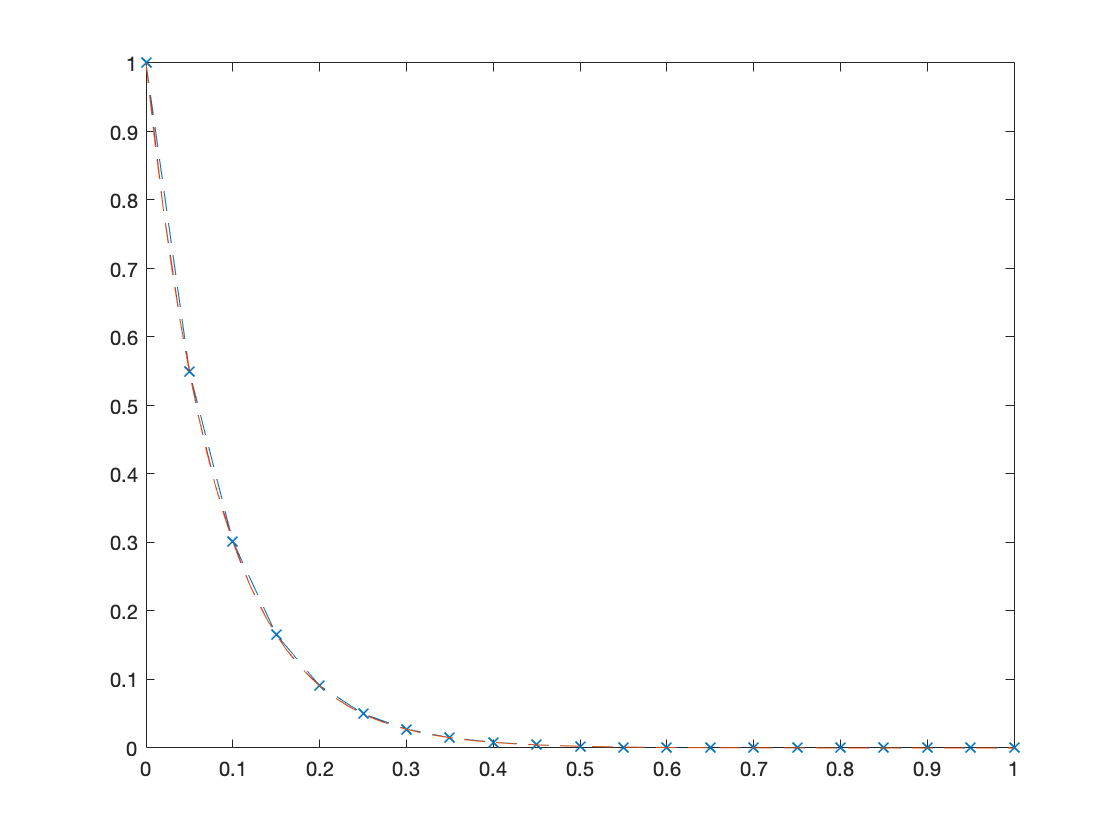


err1 = abs(y0(end) - exactSol(1));
err2 = abs(y1(end) - exactSol(1));
err3 = abs(y2(end) - exactSol(1));
Err1 = [err1, err2, err3];

plot(t0, y0, '--x', t1, y1, '--r', t2, y2, '--')

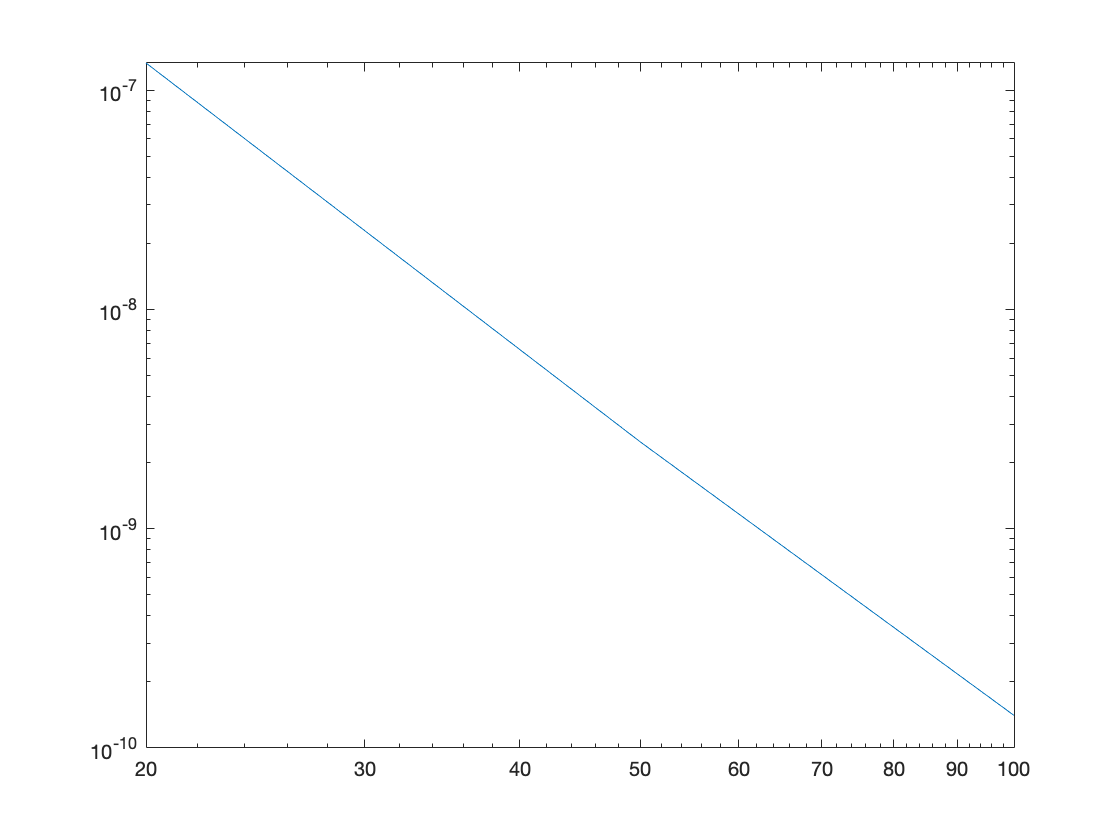

loglog(N, Err1)

function [y,t] = RK4(f, a, b, alpha, N)
h = (b-a) / N;
t = zeros(N,1);
y = zeros(N,1);
y(1) = alpha;
t(1) = a;

for i = 1:N
    t(i + 1) = a + (i) * h;
    k1 = h*f(t(i),y(i));
    k2 = h*f(t(i) + (h/2), y(i) + (1/2)*k1);
    k3 = h*f(t(i) + (h/2), y(i) + (1/2)*k2);
    k4 = h*f(t(i + 1), y(i) + k3);
    y(i + 1) = y(i) + (1/6) * (k1 + 2*k2 + 2*k3 + k4);
end
end